Read BVA formatted  data (.vhdr, .eeg and .vmrk)

clear all
% inputs
dirinput = 'W:\share_gfraga\SINEEG\Data\Pilot_October_2021';
diroutput = 'W:\share_gfraga\SINEEG\Analysis\Pilot_October_2021';

% Find files 
cd(dirinput)
measurement = 'Measurement 11' ;
filename = 'processed.vhdr';

 %% Import eeg 
EEG = pop_loadbv([dirinput, '\', measurement,'\'], filename,[], []);

pop_loadbv(): reading header file
Done.
pop_loadbv(): reading EEG data
The header file points to a binary file that does not exist
trying to open a binary file with the same name as the header
file and a different extension...
pop_loadbv(): scaling EEG data
pop_loadbv(): reading marker file
Done.
pop_loadbv() warning: data files in header and marker files inconsistent.


EEG.setname = ['eegset_',extractBefore(filename,'.vhdr')];

newsrate = 200;
for i=1:length(EEG.event)
        EEG.event(i).latency = EEG.event(i).latency / EEG.srate * newsrate;
end
EEG.srate = newsrate

EEG = struct with fields:
             setname: 'eegset_processed'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Original file: $b.eeg'
              nbchan: 32
              trials: 1
                pnts: 82354
               srate: 200
                xmin: 0
                xmax: 9.1503e+03
               times: [1×82354 double]
                data: [32×82354 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×32 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×1085 struct]
             urevent: [1×1085 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoch: []
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1

%load channel location 
EEG =pop_chanedit(EEG, 'load',{'W:\\share_gfraga\\SINEEG\\sample32chs.sph','filetype','sph'});

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Segment

EEG = eeg_checkset( EEG );
%[ALLEEG EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
%eeglab redraw
times = EEG.times

times = 	1.0e+06 *

         0    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054


dat = EEG.data

dat = 32×82354 single matrix
   -0.4634    5.3855    6.2211    5.9705    5.7849    6.2797    8.0434   10.2499   10.8451    9.7010    7.7692    5.9626    4.7447    3.8474    3.0982    3.2186    3.9068    4.3287    5.4883    6.6781    7.7506    9.3101   11.2409   13.8785   17.4575   19.8464   19.6332   17.9732   14.7272   11.4521   10.8428   12.7777   15.9442   19.8409   22.9833   23.0180   20.9280   18.5435   17.0327   16.8375   17.7948   18.4226   17.6059   16.0498   14.3211   11.1448    7.9031    6.8007    6.8446    6.6476
   -8.6475   -3.3837   -1.9564   -0.7546    0.7922    2.9969    5.2525    6.2542    5.6702    4.0751    2.8483    1.8204    0.9853    1.4173    3.0269    4.3231    5.4138    6.6815    7.0028    6.3073    6.0365    6.6374    8.0477   10.0744   11.7355   12.4366   11.9721   10.4794    8.3586    6.1413    4.2914    4.1685    5.8150    8.0276   10.0554   11.0809   10.1944    8.7748    8.0915    8.4423   10.2777   12.6373   13.4825   11.7725    8.7110    5.9353    4.2825

chans = 32×4 char array
    'FPz '
    'EOG1'
    'F3  '
    'Fz  '
    'F4  '
    'EOG2'
    'FC5 '
    'FC1 '
    'FC2 '
    'FC6 '
    'T7  '
    'C3  '
    'C4  '
    'Cz  '
    'T8  '
    'CP5 '
    'CP1 '
    'CP2 '
    'CP6 '
    'P7  '
    'P3  '
    'Pz  '
    'P4  '
    'P8  '
    'PO7 '
    'PO3 '
    'POz '
    'PO4 '
    'PO8 '
    'O1  '
    'Oz  '
    'O2  '


Time frequency analysis

%[EEG ALLEEG CURRENTSET] = eeg_retrieve(ALLEEG,1);
chans= deblank(string(char(EEG.chanlocs.labels)))

chans = 32×1 string array
    "FPz"
    "EOG1"
    "F3"
    "Fz"
    "F4"
    "EOG2"
    "FC5"
    "FC1"
    "FC2"
    "FC6"
    "T7"
    "C3"
    "C4"
    "Cz"
    "T8"
    "CP5"
    "CP1"
    "CP2"
    "CP6"
    "P7"
    "P3"
    "Pz"
    "P4"
    "P8"
    "PO7"
    "PO3"
    "POz"
    "PO4"
    "PO8"
    "O1"


chan_selected =  chans(18)

chan_selected = "CP2"

Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 1 trials
  of 82354 frames sampled at 200 Hz.
Each trial contains samples from 0 ms before to
  411765 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 819.2 at highest.
Generating 200 time points (45632.5 to 366132.5 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 18253 samples (91265 ms) wide.
Estimating 4094 linear-spaced frequencies from 0.0 Hz to 50.0 Hz.
Processing time point (of 200): 10 20 30 40 50 60 70 80 90 100 110 120
 130 140 150 160 170 180 190 200
Computing the mean baseline spectrum


Note: Add output variables to command line call in history to
      retrieve results and use the tftopo function to replot them


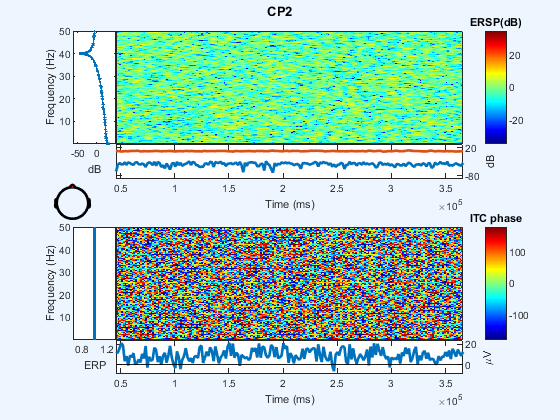


ans =

  0×0 empty char array



EEG = eeg_checkset( EEG );
figure; pop_newtimef( EEG, 1, 1, [0  411765], [3         0.8] , 'topovec', 1, 'elocs', EEG.chanlocs, 'chaninfo', EEG.chaninfo, 'caption', char(chan_selected), 'baseline',[0], 'plotphase', 'off', 'padratio', 1)


% 
%  
% data = thingSpeakRead(12397,"NumDays",2,"Timeout",10,"OutputFormat","table");
% latestValues = height(data);
% 
% useSIUnits = false;
% 
% if useSIUnits == 0
%     disp("Current Conditions: Temperature " + data.TemperatureF(latestValues) + "F, Humidity " + data.Humidity(latestValues) + "%, Wind " + data.WindSpeedmph(latestValues) + "mph")
%     
%     plotWeatherData(data.Timestamps, data.TemperatureF, "F", data.WindSpeedmph, "mph", data.Humidity)
% 
% else
%     tempC = (5/9)*(data.TemperatureF-32);
%     tempC = round(tempC,2);
%     
%     windkmh = data.WindSpeedmph*1.60934;
%     disp("Current Conditions: Temperature " + tempC(latestValues) + "C, Humidity " + data.Humidity(latestValues) + "%, Wind " + windkmh(latestValues) + "kph")
%     
%     plotWeatherData(data.Timestamps, tempC, "C", windkmh, "kph", data.Humidity)
% end
% 

% function plotWeatherData(timestamps, tempData, tempUnits, windData, windUnits, humidityData)
%     subplot(3,1,1)
%     plot(timestamps, tempData)
%     xlabel("Date")
%     ylabel("Temp (" + tempUnits + ")")
%     title("Temperature (past 2 days)")
%     
%     subplot(3,1,2)
%     plot(timestamps, humidityData)
%     xlabel("Date")
%     ylabel("Humidity (%)")
%     title("Humidity (past 2 days)")
%     
%     subplot(3,1,3)
%     plot(timestamps, windData)
%     xlabel("Date")
%     ylabel("Wind Speed (" + windUnits + ")")
%     title("Wind (past 2 days)")
% end